## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)**** definida abaixo****.*

**b) **Listen the sound with f1 = 100, f2 = 2000 and fs = 4000 Hz.

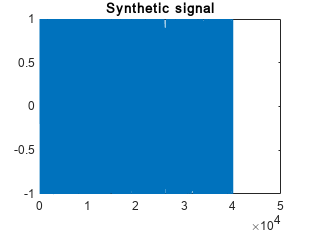

sound =     0.9996    0.9916    0.9591    0.9030    0.8245    0.7256    0.6087    0.4766    0.3327    0.1805    0.0237   -0.1338   -0.2880   -0.4351   -0.5714   -0.6935   -0.7984   -0.8833   -0.9462   -0.9854   -0.9999   -0.9893   -0.9539   -0.8945   -0.8125   -0.7100   -0.5896   -0.4542   -0.3073   -0.1525    0.0062    0.1648    0.3193    0.4657    0.6004    0.7199    0.8211    0.9015    0.9589    0.9919    0.9995    0.9816    0.9385    0.8714    0.7819    0.6723    0.5453    0.4043    0.2528    0.0948


sound = chirpTone(10,100,2000,4000)

soundsc(sound)

**c) **Save the sound vector in an audio file to be read in normal audio players

fs = 4000;
audiowrite('synthetic.wav',sound,fs);

# **2) Real data**

**a) **Audio (1D)

**i) **Read the audio file ”Let It Be.mp3”.

audioread("Let It Be.mp3");

**b) **Compute the length of the file in seconds. Explain the approach you used. 

## **c)**

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)*

function [x] = chirpTone(T,f1,f2,fs)
    stepT = 1/fs; %time step for time array
    time = 0:stepT:T; %time array
    %instead of a cosine, we introduce the phase -pi/2 for a sine
    x = chirp(time, f1, T, f2,"linear",-pi/2);
    plot (x);
    title("Synthetic signal")
end